# Immo

Inspiration: [https://github.com/slevin48/immo](https://github.com/slevin48/immo)

Data source: [https://www.data.gouv.fr/fr/datasets/5cc1b94a634f4165e96436c1/](https://www.data.gouv.fr/fr/datasets/5cc1b94a634f4165e96436c1/) 

Example in Paris (14th arrondissement)

commune = "75114";
price_min = 2500;
price_max = 12500;
date_start = datetime("2024-03-14", "InputFormat", "uuuu-MM-dd");
 
T = load_data(commune);
T = T(T.prixm2 > price_min & T.prixm2 < price_max & T.date_mutation > date_start,{'id_mutation','date_mutation','valeur_fonciere','prixm2','adresse_numero','adresse_nom_voie','latitude','longitude','marker_color'})

T = 448x9 table
      id_mutation      date_mutation    valeur_fonciere    prixm2    adresse_numero          adresse_nom_voie          latitude    longitude    marker_color
    _______________    _____________    _______________    ______    ______________    ____________________________    ________    _________    ____________

    {'2024-555170'}     28-Jun-2024         2.64e+05        8516           49          {'AV JEAN MOULIN'          }     48.825      2.3205       {'yellow'} 
    {'2024-555253'}     28-Jun-2024         1.87e+05        8130           14          {'RUE PIERRE LAROUSSE'     }     48.829      2.3152       {'yellow'} 
    {'2024-555329'}     28-Jun-2024       5.1067e

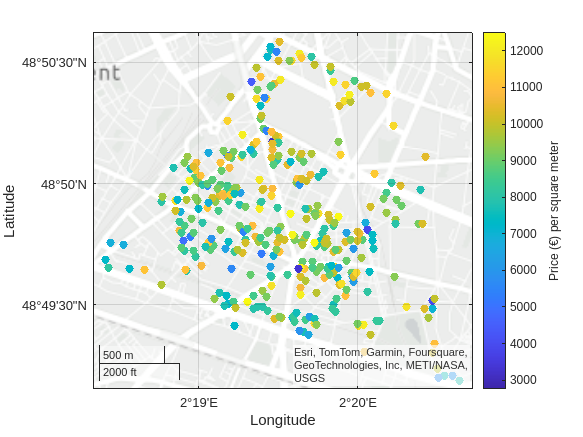

s = geoscatter(T,"latitude","longitude","filled");
s.ColorVariable = "prixm2";
c = colorbar;
c.Label.String = "Price (€) per square meter";

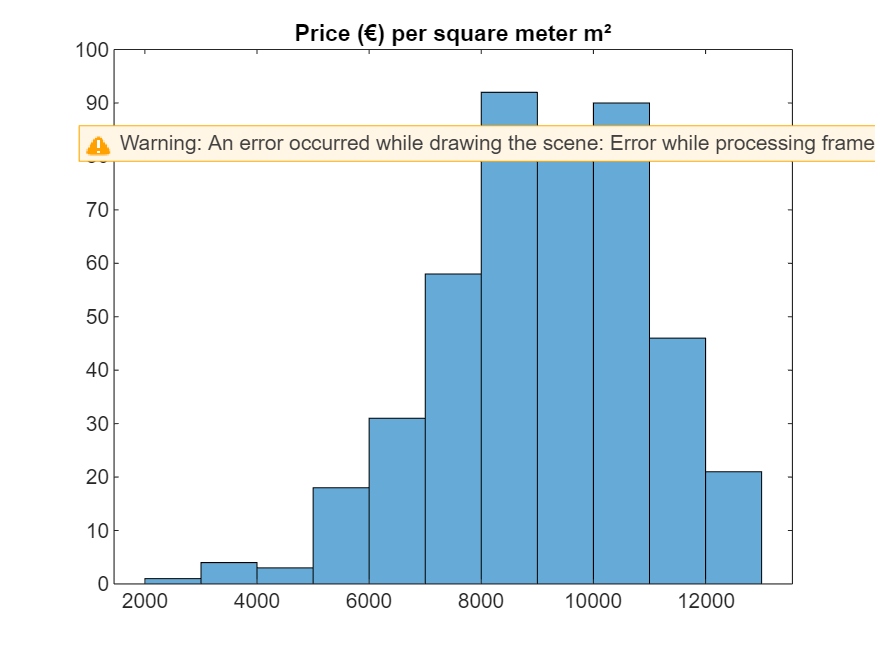

histogram(T.prixm2)
title("Price (€) per square meter m²")